# Paper3 Function Preparation

## Setting up network

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

%FigurePath = [CurrentFolder '/Figures/Demo022722/'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_Binocular/']; % V1D2
addpath(DataFolder)
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/LARGE16/']; % V1D2
addpath(DataFolder1)
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/165Function_binocular_realLGN_realL6/']; % V1D2
addpath(DataFolder2)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

CurrentFolder = pwd; % Since loaded data will overwrite pwd...
FigureFolder = [CurrentFolder '/Paper2Figs/']; % V1D2
%SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(SaveFolder)

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPt = 'V4D2';
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPt))
%load("AllMFPixPara_Paper2TuneFig1V4D2.mat")
%load("AllMFPixPara_Paper2TuneFig1V5D1.mat")
%load("AllMFPixPara_Paper2Tune.mat")
close all
CurrentFolder = pwd;
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
LargeFlag = {'S','L','Ler'};
DomList =  {'Small','Large','LARGER'};
lgnSF = 2.5;

%[19 42 66 100] to imnitate peak LGNfr = [1/4, 2/4, 3/4, 1]*(max-20) + 20, corresponding to 4, 10, 25, 64 contrast

for Contr = [19 42 66]
    switch Contr
        case 100
            ContrStr = '';
        otherwise
            ContrStr = sprintf('_Contr%d',Contr)
    end
    for lgnTF = 10 %10; 2 4 10 16 24
        for AngCtgr = 1:4% for now; last round: 22.5 broken
            for DomCtgr = 1:2%length(LargeFlag)
                fprintf('AngCat%d-Dom%d starts\n',AngCtgr,DomCtgr)
                DomFlag = LargeFlag{DomCtgr};
                DomPrint = DomList{DomCtgr};
                AngPrint = AngleList{AngCtgr};
                Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5
                switch lgnTF
                    case 10
                        if Contr == 100
                            L6up = 100;
                        else
                            L6up = 120;
                        end
                    otherwise
                        L6up = 120;
                end

                L6low = 3; %[10 54; 12 50]
                ExpTex = 'CtrlL4';
                LGNctgr = 1; L6ctgr = 33; % take the maximum

                DataPt = 'V4D2';
                LGNStr = sprintf('LGNc%d_SF%.1f_TF%d%s',LGNctgr,lgnSF, lgnTF,ContrStr);
                L6Str  = sprintf('L6c%d_uplow%d-%d_%s',L6ctgr, L6up,L6low, ExpTex);
                FileStr = sprintf(...
                    'Paper3_LIFLib_%s_Ang%.1f_%s_%s_%s.mat',...
                    DataPt, Angle, LGNStr,L6Str,DomFlag);
                load(FileStr,'L4ERcrd','L4IRcrd','f_EnIOut')
                a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);
                rowsmWin = 6; % was 30
                colswWin = 3;
                realLGN = true;
                smth = true;
                if realLGN
                    LIFN = 5;
                else
                    LIFN = 3;
                end

Load and make all 25 functions for this angle

NOTE: The new scheme include BG inputs for L6 and LGN now!

                LGNlist = 5; L6list = 40;
                LDEFrVecS = zeros(length(L4ERcrd),LGNlist,L6list);
                LDEFrVecC = zeros(length(L4ERcrd),LGNlist,L6list);
                LDEFrVecI = zeros(length(L4ERcrd),LGNlist,L6list);
                ContourInfoAll = cell(3,LGNlist,L6list); % Use this for E-I relation

                plotFlag = false;
                for LGNCtgr = 1:LGNlist
                    figure(LGNCtgr)
                    fprintf('LGNCtgr%d\n',LGNCtgr)
                    tic
                    for L6Ctgr = 1:L6list
                        switch lgnTF
                            case 10
                                if Contr == 100
                                    if L6Ctgr <= 33
                                        L6up = 100;
                                    elseif L6Ctgr > 33 && L6Ctgr <= 40
                                        L6up = 120;
                                    end
                                else
                                    L6up = 120;
                                end
                            otherwise
                                L6up = 120;
                        end

                        LGNStr = sprintf('LGNc%d_SF%.1f_TF%d%s',LGNCtgr,lgnSF, lgnTF,ContrStr);
                        L6Str  = sprintf('L6c%d_uplow%d-%d_%s',L6Ctgr, L6up,L6low, ExpTex);
                        FileStr = sprintf(...
                            'Paper3_LIFLib_%s_Ang%.1f_%s_%s_%s.mat',...
                            DataPt, Angle, LGNStr,L6Str,DomFlag);
                        %disp(FileStr)
                        if exist(FileStr) > 0
                            load(FileStr)
                        else %% 22.5: (1 4) (2 3) switchable
                            disp("Warning! File non exists, quit...")
                            break
                        end
                        L4EPlot = reshape(L4ERcrd,a2,a1);
                        L4IPlot = reshape(L4IRcrd,a2,a1);
                        FrLDE = zeros(length(f_EnIOut),LIFN);
                        for LDEInd = 1:length(f_EnIOut)
                            if ~(isempty(f_EnIOut{LDEInd}) || size(f_EnIOut{LDEInd},2)<5)
                                FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,floor(end/2):end),2))';
                            else
                                FrLDE(LDEInd,:) = nan;
                            end
                        end
                        FrLDE(FrLDE<0) = eps;
                        % S rates
                        subplot(L6list,3,(L6Ctgr-1)*3+1)
                        [LDEFrVecS(:,LGNCtgr,L6Ctgr), ContourInfoAll{1,LGNCtgr,L6Ctgr}]= ...
                            LDEPlotRateFunc_RealLGN(L4EPlot,L4IPlot,FrLDE,a1,a2,...
                            LGNCtgr,L6Ctgr,'S',smth,plotFlag,realLGN, [rowsmWin, colswWin] );

                        % C rates
                        subplot(L6list,3,(L6Ctgr-1)*3+2)
                        [LDEFrVecC(:,LGNCtgr,L6Ctgr), ContourInfoAll{2,LGNCtgr,L6Ctgr}] = ...
                            LDEPlotRateFunc_RealLGN(L4EPlot,L4IPlot,FrLDE,a1,a2,...
                            LGNCtgr,L6Ctgr,'C',smth,plotFlag,realLGN, [rowsmWin, colswWin] );

                        % I rates
                        subplot(L6list,3,(L6Ctgr-1)*3+3)
                        [LDEFrVecI(:,LGNCtgr,L6Ctgr), ContourInfoAll{3,LGNCtgr,L6Ctgr}] = ...
                            LDEPlotRateFunc_RealLGN(L4EPlot,L4IPlot,FrLDE,a1,a2,...
                            LGNCtgr,L6Ctgr,'I',smth,plotFlag,realLGN, [rowsmWin, colswWin] );
                    end
                    toc
                end
                close all

Create a function

                L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400);
                L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
                [L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);

                % 2D function now, depending on input of total E and I kick numbers\
                ItplType = 'Linear';
                for LGNCtgr = 1:LGNlist
                    tic
                    for L6Ctgr = 1:L6list
                        LDEFrfunc.S{LGNCtgr,L6Ctgr} = ...
                            griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
                        LDEFrfunc.C{LGNCtgr,L6Ctgr} = ...
                            griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
                        LDEFrfunc.I{LGNCtgr,L6Ctgr} = ...
                            griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
                    end
                    toc
                end
                %% If 22.5...may need to introduce symmetry
                if Angle == 22.5
                    LDEFrfuncUse.S = FuncSwap(LDEFrfunc.S,[1,2,3,4;4,3,2,1]);
                    LDEFrfuncUse.C = FuncSwap(LDEFrfunc.C,[1,2,3,4;4,3,2,1]);
                    LDEFrfuncUse.I = FuncSwap(LDEFrfunc.I,[1,2,3,4;4,3,2,1]);
                    LDEFrfunc = LDEFrfuncUse;
                end
                Comment = ['L6Real' ExpTex];
                tic
                save([SaveFolder sprintf('Func200%s-%s-Ang%s-SF%.1fTF%d%s-%s.mat',...
                    DataPt,Comment,AngPrint,lgnSF,lgnTF,ContrStr,DomPrint)],...
                    'LDEFrfunc','L4EmeshX','L4ImeshY')
                toc
            end
        end
    end
end

ContrStr = '_Contr19'

AngCat1-Dom1 starts


LGNCtgr1


Elapsed time is 23.385315 seconds.


LGNCtgr2


Elapsed time is 22.571939 seconds.


LGNCtgr3


Elapsed time is 22.553412 seconds.


LGNCtgr4


Elapsed time is 22.792407 seconds.


LGNCtgr5


Elapsed time is 22.556540 seconds.


Elapsed time is 76.301459 seconds.
Elapsed time is 76.234684 seconds.
Elapsed time is 76.225910 seconds.
Elapsed time is 76.882446 seconds.
Elapsed time is 75.812856 seconds.


Elapsed time is 5.498940 seconds.


AngCat1-Dom2 starts


LGNCtgr1


Elapsed time is 15.543260 seconds.


LGNCtgr2


Elapsed time is 15.572801 seconds.


LGNCtgr3


Elapsed time is 15.917138 seconds.


LGNCtgr4


Elapsed time is 16.146600 seconds.


LGNCtgr5


Elapsed time is 15.736832 seconds.


Elapsed time is 77.164751 seconds.
Elapsed time is 76.844630 seconds.
Elapsed time is 76.962893 seconds.
Elapsed time is 77.235838 seconds.
Elapsed time is 77.104500 seconds.


Elapsed time is 3.728916 seconds.


AngCat2-Dom1 starts


LGNCtgr1


Elapsed time is 22.562546 seconds.


LGNCtgr2


Elapsed time is 22.585167 seconds.


LGNCtgr3


Elapsed time is 22.523297 seconds.


LGNCtgr4


Elapsed time is 22.533424 seconds.


LGNCtgr5


Elapsed time is 22.451029 seconds.


Elapsed time is 75.886685 seconds.
Elapsed time is 75.878775 seconds.
Elapsed time is 75.893026 seconds.
Elapsed time is 78.412388 seconds.
Elapsed time is 75.960249 seconds.


Elapsed time is 5.594045 seconds.


AngCat2-Dom2 starts


LGNCtgr1


Elapsed time is 15.815146 seconds.


LGNCtgr2


Elapsed time is 15.846985 seconds.


LGNCtgr3


Elapsed time is 15.798504 seconds.


LGNCtgr4


Elapsed time is 15.832130 seconds.


LGNCtgr5


Elapsed time is 15.888053 seconds.


Elapsed time is 78.687835 seconds.
Elapsed time is 78.650061 seconds.
Elapsed time is 78.674124 seconds.
Elapsed time is 78.791442 seconds.
Elapsed time is 78.650222 seconds.


Elapsed time is 3.711823 seconds.


AngCat3-Dom1 starts


LGNCtgr1


Elapsed time is 22.494411 seconds.


LGNCtgr2


Elapsed time is 22.455674 seconds.


LGNCtgr3


Elapsed time is 22.496995 seconds.


LGNCtgr4


Elapsed time is 22.372743 seconds.


LGNCtgr5


Elapsed time is 23.323439 seconds.


Elapsed time is 75.765786 seconds.
Elapsed time is 75.772487 seconds.
Elapsed time is 75.778207 seconds.
Elapsed time is 75.837501 seconds.
Elapsed time is 75.838572 seconds.


Elapsed time is 5.487554 seconds.


AngCat3-Dom2 starts


LGNCtgr1


Elapsed time is 15.779490 seconds.


LGNCtgr2


Elapsed time is 15.786812 seconds.


LGNCtgr3


Elapsed time is 15.990748 seconds.


LGNCtgr4


Elapsed time is 15.756585 seconds.


LGNCtgr5


Elapsed time is 15.889977 seconds.


Elapsed time is 78.879597 seconds.
Elapsed time is 78.346094 seconds.
Elapsed time is 78.112393 seconds.
Elapsed time is 77.958393 seconds.
Elapsed time is 78.001120 seconds.


Elapsed time is 3.675063 seconds.


AngCat4-Dom1 starts


LGNCtgr1


Elapsed time is 22.157970 seconds.


LGNCtgr2


Elapsed time is 22.096627 seconds.


LGNCtgr3


Elapsed time is 22.123960 seconds.


LGNCtgr4


Elapsed time is 22.214047 seconds.


LGNCtgr5


Elapsed time is 22.253324 seconds.


Elapsed time is 76.195977 seconds.
Elapsed time is 76.259477 seconds.
Elapsed time is 76.205695 seconds.
Elapsed time is 76.254629 seconds.
Elapsed time is 76.374737 seconds.


Elapsed time is 5.446733 seconds.


AngCat4-Dom2 starts


LGNCtgr1


Elapsed time is 15.494862 seconds.


LGNCtgr2


Elapsed time is 15.487574 seconds.


LGNCtgr3


Elapsed time is 15.526180 seconds.


LGNCtgr4


Elapsed time is 15.510842 seconds.


LGNCtgr5


Elapsed time is 15.471764 seconds.


Elapsed time is 77.876940 seconds.
Elapsed time is 78.588257 seconds.
Elapsed time is 77.993562 seconds.
Elapsed time is 77.872215 seconds.
Elapsed time is 79.318384 seconds.


Elapsed time is 3.694966 seconds.


ContrStr = '_Contr42'

AngCat1-Dom1 starts


LGNCtgr1


Elapsed time is 22.707453 seconds.


LGNCtgr2


Elapsed time is 22.313398 seconds.


LGNCtgr3


Elapsed time is 22.271574 seconds.


LGNCtgr4


Elapsed time is 22.261344 seconds.


LGNCtgr5


Elapsed time is 22.132140 seconds.


Elapsed time is 78.367144 seconds.
Elapsed time is 78.000806 seconds.
Elapsed time is 77.757554 seconds.
Elapsed time is 78.829129 seconds.
Elapsed time is 76.961426 seconds.


Elapsed time is 5.484753 seconds.


AngCat1-Dom2 starts


LGNCtgr1


Elapsed time is 15.740155 seconds.


LGNCtgr2


Elapsed time is 15.807101 seconds.


LGNCtgr3


Elapsed time is 15.755182 seconds.


LGNCtgr4


Elapsed time is 15.749816 seconds.


LGNCtgr5


Elapsed time is 15.695115 seconds.


Elapsed time is 78.607307 seconds.
Elapsed time is 78.102323 seconds.
Elapsed time is 78.144310 seconds.
Elapsed time is 78.844848 seconds.
Elapsed time is 79.105372 seconds.


Elapsed time is 3.704830 seconds.


AngCat2-Dom1 starts


LGNCtgr1


Elapsed time is 22.547144 seconds.


LGNCtgr2


Elapsed time is 22.635669 seconds.


LGNCtgr3


Elapsed time is 22.570617 seconds.


LGNCtgr4


Elapsed time is 22.847936 seconds.


LGNCtgr5


Elapsed time is 22.636361 seconds.


Elapsed time is 76.190806 seconds.
Elapsed time is 77.321222 seconds.
Elapsed time is 77.179751 seconds.
Elapsed time is 76.421654 seconds.
Elapsed time is 76.949946 seconds.


Elapsed time is 5.483146 seconds.


AngCat2-Dom2 starts


LGNCtgr1


Elapsed time is 16.287089 seconds.


LGNCtgr2


Elapsed time is 16.174892 seconds.


LGNCtgr3


Elapsed time is 15.979271 seconds.


LGNCtgr4


Elapsed time is 16.294370 seconds.


LGNCtgr5


Elapsed time is 15.988716 seconds.


Elapsed time is 76.711443 seconds.
Elapsed time is 76.198420 seconds.
Elapsed time is 76.256855 seconds.
Elapsed time is 78.571600 seconds.
Elapsed time is 78.723900 seconds.


Elapsed time is 3.755380 seconds.


AngCat3-Dom1 starts


LGNCtgr1


Elapsed time is 23.202608 seconds.


LGNCtgr2


Elapsed time is 23.124616 seconds.


LGNCtgr3


Elapsed time is 23.268039 seconds.


LGNCtgr4


Elapsed time is 23.075773 seconds.


LGNCtgr5


Elapsed time is 22.999984 seconds.


Elapsed time is 80.146737 seconds.
Elapsed time is 77.502000 seconds.
Elapsed time is 77.621234 seconds.
Elapsed time is 77.163331 seconds.
Elapsed time is 77.408108 seconds.


Elapsed time is 5.567566 seconds.


AngCat3-Dom2 starts


LGNCtgr1


Elapsed time is 15.846644 seconds.


LGNCtgr2


Elapsed time is 15.762953 seconds.


LGNCtgr3


Elapsed time is 15.842020 seconds.


LGNCtgr4


Elapsed time is 16.050992 seconds.


LGNCtgr5


Elapsed time is 16.114251 seconds.


Elapsed time is 80.576211 seconds.
Elapsed time is 79.495083 seconds.
Elapsed time is 79.643253 seconds.
Elapsed time is 79.788261 seconds.
Elapsed time is 78.703148 seconds.


Elapsed time is 3.706095 seconds.


AngCat4-Dom1 starts


LGNCtgr1


Elapsed time is 22.555195 seconds.


LGNCtgr2


Elapsed time is 22.547909 seconds.


LGNCtgr3


Elapsed time is 22.676408 seconds.


LGNCtgr4


Elapsed time is 22.591208 seconds.


LGNCtgr5


Elapsed time is 22.628341 seconds.


Elapsed time is 77.312094 seconds.
Elapsed time is 76.633794 seconds.
Elapsed time is 78.393700 seconds.
Elapsed time is 76.693910 seconds.
Elapsed time is 77.992260 seconds.


Elapsed time is 5.512039 seconds.


AngCat4-Dom2 starts


LGNCtgr1


Elapsed time is 16.012247 seconds.


LGNCtgr2


Elapsed time is 15.953039 seconds.


LGNCtgr3


Elapsed time is 15.968234 seconds.


LGNCtgr4


Elapsed time is 15.980616 seconds.


LGNCtgr5


Elapsed time is 15.902698 seconds.


Elapsed time is 79.902691 seconds.
Elapsed time is 78.370516 seconds.
Elapsed time is 79.105019 seconds.
Elapsed time is 78.393157 seconds.
Elapsed time is 78.595450 seconds.


Elapsed time is 3.701678 seconds.


ContrStr = '_Contr66'

AngCat1-Dom1 starts


LGNCtgr1


Elapsed time is 23.265953 seconds.


LGNCtgr2


Elapsed time is 23.590145 seconds.


LGNCtgr3


Elapsed time is 23.497228 seconds.


LGNCtgr4


Elapsed time is 22.884501 seconds.


LGNCtgr5


Elapsed time is 22.327225 seconds.


Elapsed time is 76.526376 seconds.
Elapsed time is 77.182522 seconds.
Elapsed time is 77.057740 seconds.
Elapsed time is 77.223606 seconds.
Elapsed time is 76.582003 seconds.


Elapsed time is 5.463809 seconds.


AngCat1-Dom2 starts


LGNCtgr1


Elapsed time is 15.915525 seconds.


LGNCtgr2


Elapsed time is 15.737346 seconds.


LGNCtgr3


Elapsed time is 15.823083 seconds.


LGNCtgr4


Elapsed time is 15.972401 seconds.


LGNCtgr5


Elapsed time is 16.036483 seconds.


Elapsed time is 78.769661 seconds.
Elapsed time is 78.993291 seconds.
Elapsed time is 80.411428 seconds.
Elapsed time is 80.196765 seconds.
Elapsed time is 78.688776 seconds.


Elapsed time is 3.762623 seconds.


AngCat2-Dom1 starts


LGNCtgr1


Elapsed time is 22.571647 seconds.


LGNCtgr2


Elapsed time is 22.656699 seconds.


LGNCtgr3


Elapsed time is 22.376839 seconds.


LGNCtgr4


Elapsed time is 22.408855 seconds.


LGNCtgr5


Elapsed time is 22.646065 seconds.


Elapsed time is 76.638749 seconds.
Elapsed time is 77.709050 seconds.
Elapsed time is 76.415316 seconds.
Elapsed time is 77.380227 seconds.
Elapsed time is 77.024885 seconds.


Elapsed time is 5.534195 seconds.


AngCat2-Dom2 starts


LGNCtgr1


Elapsed time is 15.820230 seconds.


LGNCtgr2


Elapsed time is 15.714269 seconds.


LGNCtgr3


Elapsed time is 15.709482 seconds.


LGNCtgr4


Elapsed time is 15.926415 seconds.


LGNCtgr5


Elapsed time is 16.215560 seconds.


Elapsed time is 80.777702 seconds.
Elapsed time is 78.652755 seconds.
Elapsed time is 78.273871 seconds.
Elapsed time is 78.836858 seconds.
Elapsed time is 79.294925 seconds.


Elapsed time is 3.975690 seconds.


AngCat3-Dom1 starts


LGNCtgr1


Elapsed time is 23.034646 seconds.


LGNCtgr2


Elapsed time is 22.763511 seconds.


LGNCtgr3


Elapsed time is 23.210416 seconds.


LGNCtgr4


Elapsed time is 23.628572 seconds.


LGNCtgr5


Elapsed time is 23.378052 seconds.


Elapsed time is 78.654954 seconds.
Elapsed time is 76.764334 seconds.
Elapsed time is 77.054707 seconds.
Elapsed time is 76.787658 seconds.
Elapsed time is 76.887174 seconds.


Elapsed time is 5.573567 seconds.


AngCat3-Dom2 starts


LGNCtgr1


Elapsed time is 16.474453 seconds.


LGNCtgr2


Elapsed time is 16.270680 seconds.


LGNCtgr3


Elapsed time is 16.571816 seconds.


LGNCtgr4


Elapsed time is 16.523868 seconds.


LGNCtgr5


Elapsed time is 16.280523 seconds.


Elapsed time is 79.210150 seconds.
Elapsed time is 79.675376 seconds.
Elapsed time is 81.157796 seconds.
Elapsed time is 81.836503 seconds.
Elapsed time is 80.740616 seconds.


Elapsed time is 3.773795 seconds.


AngCat4-Dom1 starts


LGNCtgr1


Elapsed time is 23.498668 seconds.


LGNCtgr2


Elapsed time is 22.504269 seconds.


LGNCtgr3


Elapsed time is 22.541341 seconds.


LGNCtgr4


Elapsed time is 22.521871 seconds.


LGNCtgr5


Elapsed time is 22.498466 seconds.


Elapsed time is 76.841263 seconds.
Elapsed time is 77.010473 seconds.
Elapsed time is 78.013469 seconds.
Elapsed time is 77.052726 seconds.
Elapsed time is 77.557891 seconds.


Elapsed time is 5.666219 seconds.


AngCat4-Dom2 starts


LGNCtgr1


Elapsed time is 16.796565 seconds.


LGNCtgr2


Elapsed time is 16.239505 seconds.


LGNCtgr3


Elapsed time is 15.831297 seconds.


LGNCtgr4


Elapsed time is 15.725968 seconds.


LGNCtgr5


Elapsed time is 15.880654 seconds.


Elapsed time is 78.304663 seconds.
Elapsed time is 78.639317 seconds.
Elapsed time is 80.678397 seconds.
Elapsed time is 79.516256 seconds.
Elapsed time is 79.050756 seconds.


Elapsed time is 3.826834 seconds.


%% BElow are unadjusted and should not be directly run

Compare realLGN and fake local response functions

Contr = 100;
    switch Contr
        case 100
            ContrStr = '';
        otherwise
            ContrStr = sprintf('_Contr%d',Contr)
    end

AngleList = {'0.0','7.5','15.0','22.5'};
LargeFlag = {'S','L','Ler'};
DomList =  {'Small','Large','LARGER'};
ExpTex = 'CtrlL4';
Comment = ['L6Real' ExpTex];
lgnSF = 2.5; lgnTF = 10;
DomCtgr = 1;
DomFlag = LargeFlag{DomCtgr};
DomPrint = DomList{DomCtgr};
AngPrint = AngleList{1};
LRF_real = load([sprintf('Func200%s-%s-Ang%s-SF%.1fTF%d%s-%s.mat',...
                    DataPt,Comment,AngPrint,lgnSF,lgnTF,ContrStr,DomPrint)],...
    'LDEFrfunc','L4EmeshX','L4ImeshY');
%LRF_fake = load([sprintf('Func25%sAng%s-SF%.1fTF%d-%s.mat',DataPt,AngPrint,lgnSF,lgnTF,DomPrint)],...
%    'LDEFrfunc','L4EmeshX','L4ImeshY');

% LRF_fake = load([sprintf('Func25%sAng%s%s.mat',DataPt,AngPrint,DomPrint)],...
%             'LDEFrfunc','L4EmeshX','L4ImeshY');
L4EmeshX = LRF_real.L4EmeshX;
L4ImeshY = LRF_real.L4ImeshY;

make figure

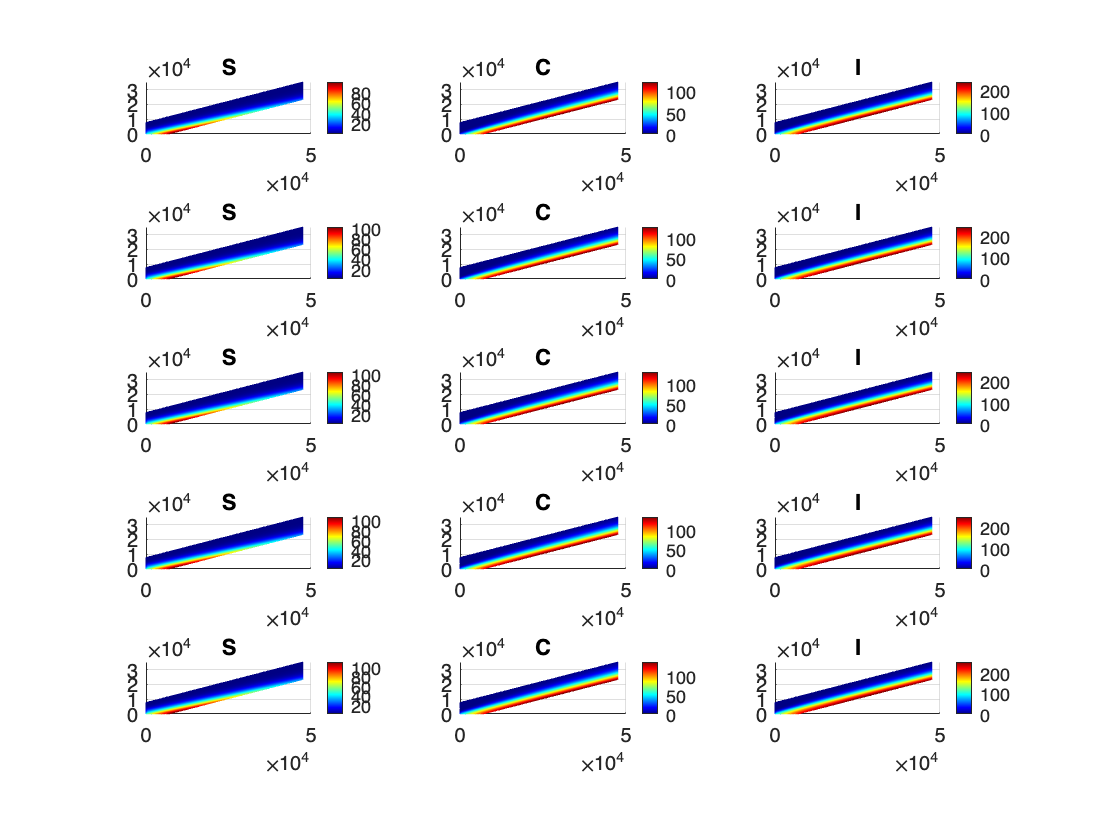

close all
figure(2)
L6list = 5;
% for L6Ctgr = 1:L6list
%     % S rate diff
%     subplot(L6list,3,(L6Ctgr-1)*3+1)
%     mesh(L4EmeshX,L4ImeshY,...
%         LRF_real.LDEFrfunc.S{1,L6Ctgr} - LRF_fake.LDEFrfunc.S{1,L6Ctgr} )
%     colormap jet
%     colorbar
%     %caxis([-5 5])
%     view([0 90])
%     title('S')
%     % C rate diff
%     subplot(L6list,3,(L6Ctgr-1)*3+2)
%     mesh(L4EmeshX,L4ImeshY,...
%         LRF_real.LDEFrfunc.C{1,L6Ctgr} - LRF_fake.LDEFrfunc.C{1,L6Ctgr} )
%     colormap jet
%     colorbar
%     %caxis([-5 5])
%     view([0 90])
%     title('C')
%     % C rate diff
%     subplot(L6list,3,(L6Ctgr-1)*3+3)
%     mesh(L4EmeshX,L4ImeshY,...
%         LRF_real.LDEFrfunc.I{1,L6Ctgr} - LRF_fake.LDEFrfunc.I{1,L6Ctgr} )
%     colormap jet
%     colorbar
%     %caxis([-5 5])
%     view([0 90])
%     title('I')
% end
figure(3)
for L6Ctgr = 1:L6list
    % S rate diff
    subplot(L6list,3,(L6Ctgr-1)*3+1)
    hold on
    contour3(L4EmeshX,L4ImeshY,...
        LRF_real.LDEFrfunc.S{1,L6Ctgr},[1:10,15:5:80],'-r','LineWidth',2,'ShowText','on')
    mesh(L4EmeshX,L4ImeshY,...
        LRF_real.LDEFrfunc.S{1,L6Ctgr})
    colormap jet
    colorbar
    %caxis([-5 5])
    view([0 90])
    title('S')
    % C rate diff
    subplot(L6list,3,(L6Ctgr-1)*3+2)
    mesh(L4EmeshX,L4ImeshY,...
        LRF_real.LDEFrfunc.C{1,L6Ctgr} )
    colormap jet
    colorbar
    %caxis([-5 5])
    view([0 90])
    title('C')
    % C rate diff
    subplot(L6list,3,(L6Ctgr-1)*3+3)
    mesh(L4EmeshX,L4ImeshY,...
        LRF_real.LDEFrfunc.I{1,L6Ctgr} )
    colormap jet
    colorbar
    %caxis([-5 5])
    view([0 90])
    title('I')
end